# Non-Isentropic Ramjet Calculator

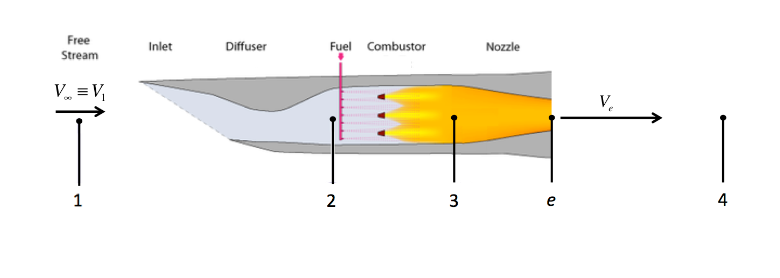

Input

- alt: in m

- eta_d 

- eta_n

- A_e

- M1

- M2

- Tt3_max: in k

- qf: j/kg

Output

- T - Static Temperatures in form [T1, T2, T3, Te, T4]

- Tt - Total Temperatures in form [Tt1, Tt2, Tt3, Tte, Tt4]

- P - Static Pressure (kPa) in form [P1, P2, P3, Pe, P4]

- Pt - Total Pressure (kPa) in form [Pt1, Pt2, Pt3, Pte, Pt4]

- V- air speed in form [V1, V2, V3, Ve, V4]

- M- mach numbers in form [M1, M2, M3, Me, M4]

- Cp- in form [cp_1, cp_2, cp_3, cp_e, cp_4]

- deltaS = in form [deltaS_12, deltaS_23, deltaS_3e, deltaS_e4, deltaS_13, deltaS_1e, deltaS_14]

- Thermal_efficiency

- Propulsive_efficiency

- Overall_efficiency

- Power

- Thrust

- Isp

- TSFC (kg/hr/N)

- MassFlux- in form [mi,me, mf]

- f

function [T, Tt, P, Pt, V, M, cp, deltaS, Thermal_efficiency, Propulsive_efficiency, Overall_efficiency, Power,Thrust, Isp, TSFC, MassFlux, f, q23] = RamjetCalculator(alt, eta_d, eta_n, A_e, M1, M2, Tt3_max, qf)

## Constants

R = 286.9;
gamma_12= 1.4;
gamma_23= 1.3;
gamma_3e= 1.3;
gamma_e4= 1.3;

## State Calculations

Returns T, Tt, P, Pt, M ,v

### State 1 (module 1)

[T1,P1,~,~]=IsenAltModel(alt);
a1= sqrt(gamma_12*R*T1);
Pt1=TotalToStaticPressureRel([],P1,M1,gamma_12);
Tt1=TotalToStaticTemperatureRel([],T1,M1,gamma_12);
V1 = M1*a1;
cp_1 = gamma_12*R / (gamma_12-1);

### State 2 (module 2)

Tt2 = Tt1; %no w or q
T2 = TotalToStaticTemperatureRel(Tt2,[],M2,gamma_12);

Pt2 = P1*(1+eta_d*((gamma_12-1.)/2).*M1.^2).^(gamma_12./(gamma_12-1));
P2 = TotalToStaticPressureRel(Pt2,[],M2,gamma_12);

a2 = sqrt(gamma_12*T2*R);
V2= a2*M2;

cp_2= cp_1;
deltaS_12 = cp_2*log(Tt2/Tt1) - R*log(Pt2/Pt1);

### State 3 (module 3)

#### Check if we are thermally choked:

Tt3_choked = Tt2*( (1/(2*(gamma_23+1))) * (1/M2^2) * (1+gamma_23*M2^2)^2 * (1+((gamma_23-1)./2).*M2.^2)^-1);

if(Tt3_choked<Tt3_max)
    Tt3 = Tt3_choked;
    M3 = 1;
    %disp('Combustor Thermally Choked')
else
    Tt3=Tt3_max;
    fun = @(M3)M3Solver(M3, Tt3, Tt2,M2, gamma_23);
    M3_0 = .5;
    options = optimoptions('fsolve', 'MaxFunctionEvaluations',5000, 'MaxIterations',5000, Display='none');
    M3 = fsolve(fun,M3_0,options);
    %disp('Combustor is not Thermally Choked: Tt3 Materially Limited')
end

q23 = 986*(Tt3-Tt2)+0.5*0.179*(Tt3^2-Tt2^2);
P3 = P2; %const. p heat addition
T3 =  TotalToStaticTemperatureRel(Tt3,[],M3,gamma_23);
Pt3 =  TotalToStaticPressureRel([],P3,M3,gamma_23);
a3 = sqrt(gamma_23*T3*R);
V3 = a3*M3;
cp_3 = 986+0.179*T3;
deltaS_23 = cp_3*log(Tt3/Tt2) - R*log(Pt3/Pt2);

deltaS_13 = deltaS_23+ deltaS_12;

### Nozzle (module 4)

#### Is the Nozzle Choked?

Test_Mach_num = sqrt((2/(gamma_3e-1)) * ((eta_n*(1-(P1/Pt3)^((gamma_3e-1)/gamma_3e)))/(1-eta_n*(1-(P1/Pt3)^((gamma_3e-1)/gamma_3e)))));

if (Test_Mach_num<1)
    %disp('Nozzle is not Choked')
    Me = Test_Mach_num;
    Pe =P1;

else 
    %disp('Nozzle is Choked')
    Me = 1;
    Pe = Pt3*(1-(1/eta_n)*((gamma_3e-1)/(gamma_3e+1)))^(gamma_3e/(gamma_3e-1));
end

### Nozzle Exit

Tte = Tt3;

Pte = TotalToStaticPressureRel([],Pe,Me,gamma_3e);
Te =  TotalToStaticTemperatureRel(Tte,[],Me,gamma_3e);

ae = sqrt(gamma_3e*Te*R);
Ve = ae*Me;

cp_e = 986+0.179*Te;
deltaS_3e = cp_e*log(Tte/Tt3) - R*log(Pte/Pt3);
deltaS_1e = deltaS_23+ deltaS_12+deltaS_3e;

mass_flux_exit = (Pe/(R*Te))*Ve*A_e;

### State 4 (module 5)

if (Test_Mach_num<1)
    eta_n_ext = 1;
else
    eta_n_ext = Test_Mach_num^-.3;
end

P4 = P1;
Tt4= Tte;

T4 = Tt4*(1-eta_n_ext*(1-(P1/Pte)^((gamma_e4-1)/gamma_e4)));

M4 = TotalToStaticTemperatureRel(Tt4,T4,[],gamma_e4);
Pt4 = TotalToStaticPressureRel([],P4,M4,gamma_e4);

a4 = sqrt(gamma_e4*T4*R);
V4 = a4*M4;

cp_4 = 986+0.179*T4;
deltaS_e4 = cp_4*log(Tt4/Tte) - R*log(Pt4/Pte);
deltaS_14 = deltaS_23+ deltaS_12+deltaS_3e+deltaS_e4;

## Engine Performance (module 6)

Returns Thrust, prop. power, eta_th, eta_p, overall eta, fuel mass flux, TSFC, Isp

mass_flux_inlet = mass_flux_exit/(1+(q23/qf));
mass_flux_fuel = mass_flux_inlet*(q23/qf);
f = mass_flux_fuel/mass_flux_inlet;
Thrust = mass_flux_inlet*((1+f)*Ve-V1) + (Pe-P1)*A_e;
TSFC = 3600*mass_flux_fuel/Thrust;
Isp = Thrust/(9.8*mass_flux_fuel);
Veq = Ve + (Pe-P1)*(A_e/mass_flux_exit);
Propulsive_efficiency = 2/(1+Veq/V1);
Thermal_efficiency = ((mass_flux_exit*.5*Veq^2)-(mass_flux_inlet*.5*V1^2))/(mass_flux_inlet*q23);
Overall_efficiency = Propulsive_efficiency*Thermal_efficiency;
Power = Thrust*V1;

T= [T1, T2, T3, Te, T4];
Tt = [Tt1, Tt2, Tt3, Tte, Tt4];
P= [P1, P2, P3, Pe, P4]/1000;
Pt=[Pt1, Pt2, Pt3, Pte, Pt4]/1000;
V=[V1, V2, V3, Ve, V4];
M= [M1, M2, M3, Me, M4];
cp=[cp_1, cp_2, cp_3, cp_e, cp_4];
deltaS= [deltaS_12, deltaS_23, deltaS_3e, deltaS_e4, deltaS_13, deltaS_1e, deltaS_14];
MassFlux = [mass_flux_inlet, mass_flux_exit, mass_flux_fuel];

end

function F = M3Solver(M3, Tt3, Tt2,M2, gamma_23)
F = ((M3/M2)^2 * ((1+gamma_23*M2^2)/(1+gamma_23*M3^2))^2 * ((1+((gamma_23-1)./2).*M3.^2)/(1+((gamma_23-1)./2).*M2.^2))) - Tt3/Tt2;
end